close all
clear all
g = 9.7949;
L = 97.95e-3; % mm
k = 93.5e-3 * g / L; % N/m
mk = 28e-3; % kg
m = 214.8e-3;
Na = 224;
la = 122.4e-3 ;
Nb = 236;
lb = 124.6e-3; %mm
beta = 1/3;
omega0_theor = sqrt(k / (m + mk * beta))

omega0_theor = 6.4588

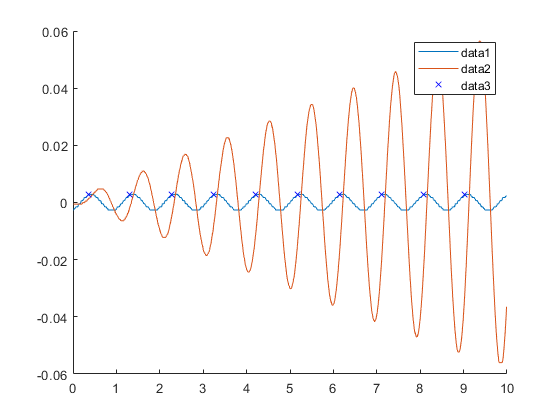




[t, countA, countB] = importfile("d:\resonanse.txt");
xa = countA / Na * la;
xb = countB / Nb * lb;
mask = t < 10;
t = t(mask);
xa = xa(mask);
xb = xb(mask);
xa = xa - mean(xa);
xb = xb - mean(xb);

[peaks, locs] = findpeaks(xa);
hold on
plot(t, xa)
plot(t, xb)
plot(t(locs), xa(locs), 'bx')
legend('AutoUpdate',"off")
hold off


T = diff(t(locs));
omega0 = 2 * pi ./ T;
omega0_meas = mean(omega0)

omega0_meas = 6.5150

omega0_err = std(omega0)

omega0_err = 0.0356

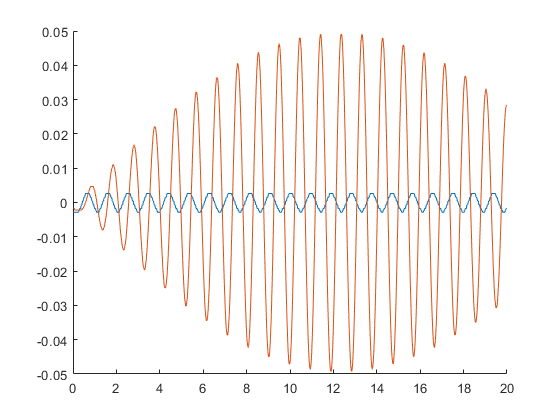

[t, countA, countB] = importfile("d:\over2.txt");
xa = countA / Na * la;
xb = countB / Nb * lb;
xa = xa - mean(xa);
xb = xb - mean(xb);
mask = t < 20;
t = t(mask);
xa = xa(mask);
xb = xb(mask);

figure()
hold on
plot(t, xa)
plot(t, xb)
hold off

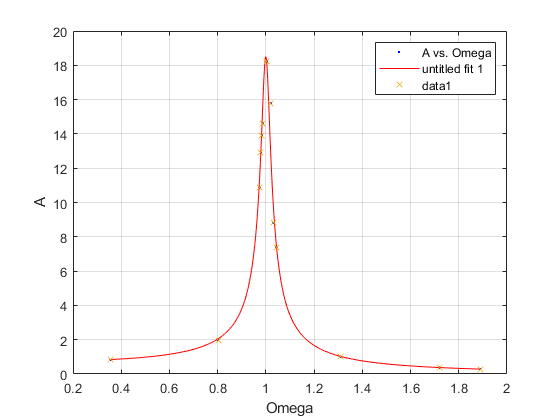

fitresult =      General model:
     fitresult(om) = b /sqrt((1-om^2)^2 + (om/Q)^2)
     Coefficients (with 95% confidence bounds):
       Q =       25.11  (18.56, 31.67)
       b =      0.7366  (0.6107, 0.8625)

gof = struct with fields:
           sse: 12.0157
       rsquare: 0.9774
           dfe: 11
    adjrsquare: 0.9753
          rmse: 1.0451


A = [];
Phi = [];
Omega = [];
for i=1 : 13
    filename = "d:\" + int2str(i)+".txt";
    [t, countA, countB] = importfile(filename);
    xa = countA / Na * la;
    xb = countB / Nb * lb;
    xa = xa - mean(xa);
    xb = xb - mean(xb);
    [peaks, locs] = findpeaks(xa);
    T = mean(diff(t(locs)));
    omega = 2 * pi / T;
    [amp, phase] = response(xa, xb);
    A(end+1) =  amp;
    Phi(end+1) = phase;
    Omega(end+1) = omega / omega0_theor;
end

hold on
plot(Omega, A, 'x')
[fitresult, gof] = createFit(Omega, A)

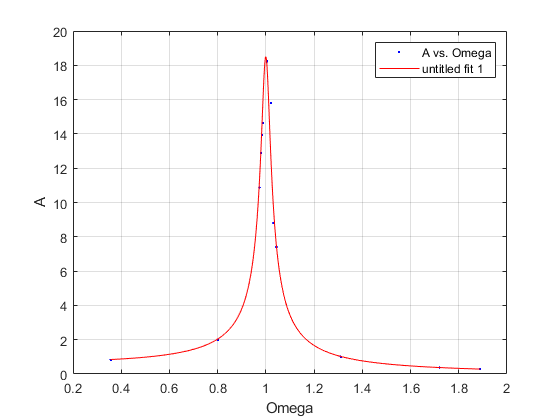

hold off

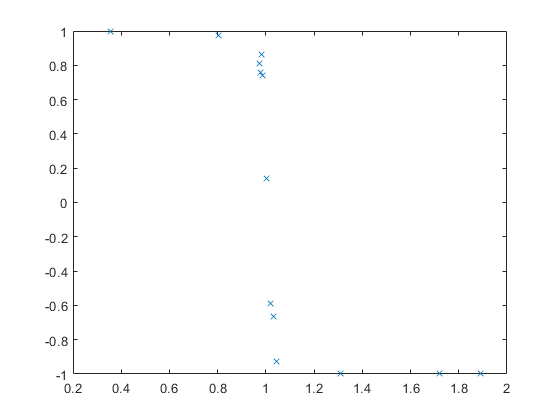



figure()
plot(Omega, Phi, 'x')

function [t, countA, countB] = importfile(filename, dataLines)
%IMPORTFILE Import data from a text file
%  [T, COUNTA, COUNTB] = IMPORTFILE(FILENAME) reads data from text file
%  FILENAME for the default selection.  Returns the data as column
%  vectors.
%
%  [T, COUNTA, COUNTB] = IMPORTFILE(FILE, DATALINES) reads data for the
%  specified row interval(s) of text file FILENAME. Specify DATALINES as
%  a positive scalar integer or a N-by-2 array of positive scalar
%  integers for dis-contiguous row intervals.
%
%  Example:
%  [t, countA, countB] = importfile("D:\resonanse.txt", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 07-Jan-2025 00:34:01

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Var1", "t", "countA", "countB", "Var5", "Var6"];
opts.SelectedVariableNames = ["t", "countA", "countB"];
opts.VariableTypes = ["string", "double", "double", "double", "string", "string"];

% Specify file level properties
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var5", "Var6"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var5", "Var6"], "EmptyFieldRule", "auto");

% Import the data
tbl = readtable(filename, opts);

%% Convert to output type
t = tbl.t;
countA = tbl.countA;
countB = tbl.countB;
end

function [amplitude,cosphi] = response(xa, xb)

a = sqrt(dot(xa, xa));
b = sqrt(dot(xb, xb));
ab = dot(xa, xb);
amplitude = b / a;
cosphi = ab / a/ b;
end

function [fitresult, gof] = createFit(Omega, A)
%CREATEFIT(OMEGA,A)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : Omega
%      Y Output: A
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 07-Jan-2025 02:21:49


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( Omega, A );

% Set up fittype and options.
ft = fittype( 'b /sqrt((1-om^2)^2 + (om/Q)^2)', 'independent', 'om', 'dependent', 'A' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.118997681558377 0.498364051982143];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'A vs. Omega', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Omega', 'Interpreter', 'none' );
ylabel( 'A', 'Interpreter', 'none' );
grid on
end